fileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\EEA List\20080326.001_bc_15sec-full_v1.h5';
data = read_h5_data(fileStr,'/conductivity/');


## Parsing variables

Ne = data.Data{2};
Ne(Ne<10^6) = 10^6;

sigmaH = data.Data{3};
sigmaP = data.Data{4};
alt = data.Data{1};
time = data.Data{5};


## Yiqun Yu's Conductivities

baseStr = 'G:\My Drive\Research\Projects\Yiqun Yu\GLOW_output.tar\GLOW_output\GLOW_output_one_point_at_';
yiqun.Ar.tha=extract_yiqun_ascii([baseStr,'lc_tha_Ar.dat']);
yiqun.Ar.thd=extract_yiqun_ascii([baseStr,'lc_thd_Ar.dat']);
yiqun.Ar.the=extract_yiqun_ascii([baseStr,'lc_the_Ar.dat']);
yiqun.Li.tha=extract_yiqun_ascii([baseStr,'lc_tha_Li.dat']);
yiqun.Li.thd=extract_yiqun_ascii([baseStr,'lc_thd_Li.dat']);
yiqun.Li.the=extract_yiqun_ascii([baseStr,'lc_the_Li.dat']);
yiqun.Yi.tha=extract_yiqun_ascii([baseStr,'lc_tha_Yi.dat']);
yiqun.Yi.thd=extract_yiqun_ascii([baseStr,'lc_thd_Yi.dat']);
yiqun.Yi.the=extract_yiqun_ascii([baseStr,'lc_the_Yi.dat']);

## Plotting

iBeam = 13;
DregionAltIndx = find_altitude(alt(iBeam,:)',70):1:find_altitude(alt(iBeam,:)',97); 
EregionAltIndx = find_altitude(alt(iBeam,:)',97)+1:1:find_altitude(alt(iBeam,:)',160);

h = figure;
timeMinStr = '26-Mar-2008 09:00';
timeMaxStr = '26-Mar-2008 12:30';
p = create_panels(h,'totalPanelNo',6,'panelHeight',30);
t = datetime(datevec(time));
% figure;
colormap(inferno);
% q = p(1);
yaxisLim = [70 160];
xaxisLim = [datetime(timeMinStr), datetime(timeMaxStr)];
p(1,1).select();
inputNe = squeeze(Ne(:,iBeam,:));
inputNe = interp_nans(inputNe);
DNe  = integrate_altitude(alt(iBeam,DregionAltIndx),inputNe(:,DregionAltIndx));
ENe  = integrate_altitude(alt(iBeam,EregionAltIndx),inputNe(:,EregionAltIndx));
TNe  = integrate_altitude(alt(iBeam,[DregionAltIndx,EregionAltIndx]),...
    inputNe(:,[DregionAltIndx,EregionAltIndx]));
plot_2D_time_series(time,alt(iBeam,:),log10(inputNe'),0.25,0); 
colorbar;
caxis([9,12]);
ylim(yaxisLim);
xlim(datenum(xaxisLim));
ylabel({'N_e [m^-^3]','Alt [km]'});
% label_time_axis(time,false,0.25);
% grid on;

p(1,3).select();
sigmaH1 = squeeze(sigmaH(:,iBeam,:));
sigmaH1(sigmaH1<=0) = 10^-8;
sigmaH1 = interp_nans(sigmaH1);
DH  = integrate_altitude(alt(iBeam,DregionAltIndx),sigmaH1(:,DregionAltIndx));
EH  = integrate_altitude(alt(iBeam,EregionAltIndx),sigmaH1(:,EregionAltIndx));
TH  = integrate_altitude(alt(iBeam,[DregionAltIndx,EregionAltIndx]),...
    sigmaH1(:,[DregionAltIndx,EregionAltIndx]));
plot_2D_time_series(time,alt(iBeam,:),log10(sigmaH1)',0.25,0); 
colorbar;
caxis([-6,-2]);
ylim(yaxisLim);
xlim(datenum(xaxisLim));
ylabel({'\sigma_H [S/m]','Alt [km]'});
% label_time_axis(time,false,0.25);

p(1,5).select();
sigmaP1 = squeeze(sigmaP(:,iBeam,:));
sigmaP1(sigmaP1<=0) = 10^-8;
sigmaP1 = interp_nans(sigmaP1);
DP  = integrate_altitude(alt(iBeam,DregionAltIndx),sigmaP1(:,DregionAltIndx));
EP  = integrate_altitude(alt(iBeam,EregionAltIndx),sigmaP1(:,EregionAltIndx));
TP  = integrate_altitude(alt(iBeam,[DregionAltIndx,EregionAltIndx]),...
    sigmaP1(:,[DregionAltIndx,EregionAltIndx]));
plot_2D_time_series(time,alt(iBeam,:),log10(sigmaP1)',0.25,0); 
colorbar;
caxis([-7,-3]);
ylim(yaxisLim);
xlim(datenum(xaxisLim));
ylabel({'\sigma_P [S/m]','Alt [km]'});
% label_time_axis(time,false,0.25);

## Plot percentages

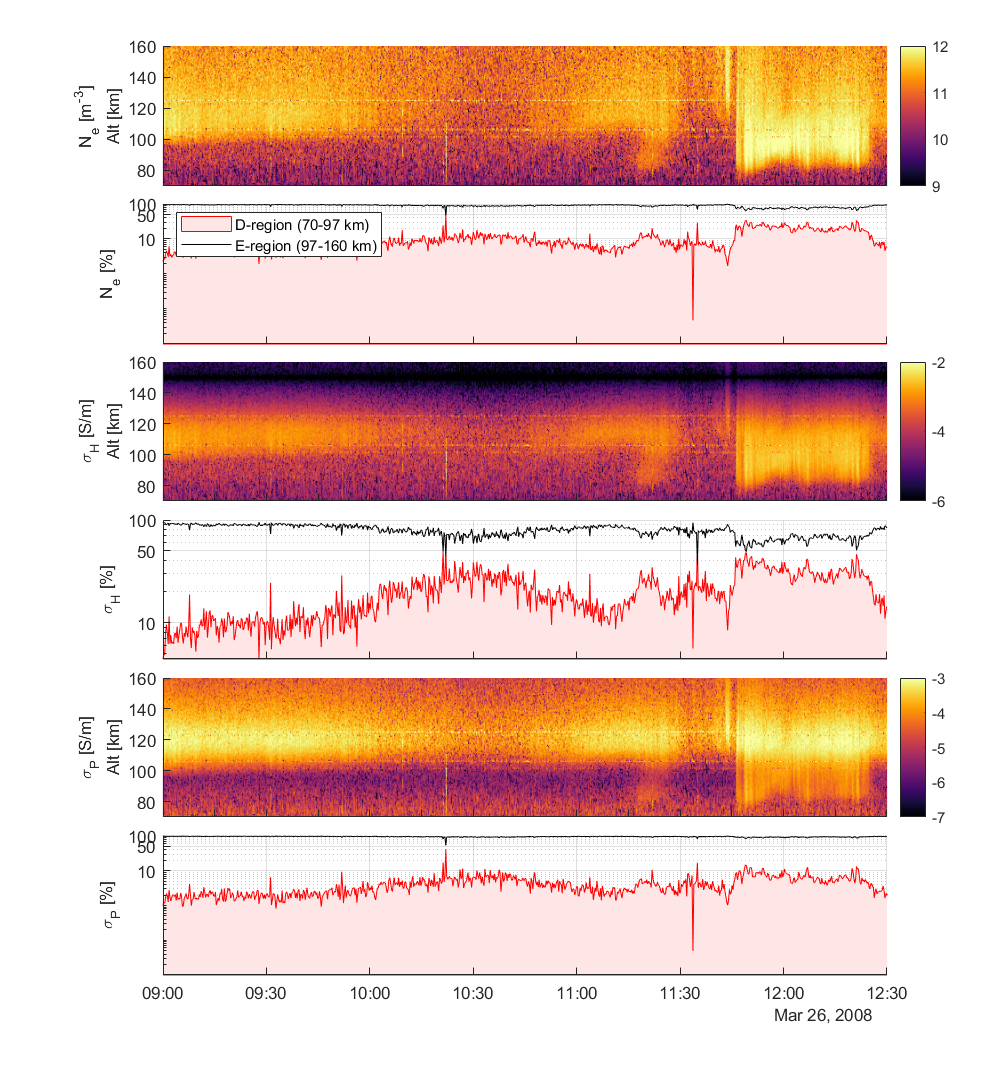


yaxisLim = [0 100];
xaxisLim = [datetime(timeMinStr), datetime(timeMaxStr)];
p(1,2).select();
area(t,100*DNe./TNe,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
plot(t,100*ENe./TNe,'k');
set(gca,'XTickLabel','','YScale','log');
set(gca,'YTick',[0,10,50,100]);
grid on;
ylabel('N_e [%]');
legend('D-region (70-97 km)','E-region (97-160 km)','Location','northwest');
xlim(xaxisLim);
% label_time_axis(time,false,0.5);

hold on;
p(1,4).select();
area(t,100*DH./TH,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
plot(t,100*EH./TH,'k');
set(gca,'XTickLabel','','YScale','log');
set(gca,'YTick',[0,10,50,100]);
grid on;
ylabel('\sigma_H [%]');
xlim(xaxisLim);
% label_time_axis(time,false,0.5);

hold on;
p(1,6).select();
area(t,100*DP./TP,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
plot(t,100*EP./TP,'k');
set(gca,'YScale','log');
set(gca,'YTick',[0,10,50,100]);
grid on;
ylabel('\sigma_P [%]');
xlim(xaxisLim);

% label_time_axis(time,true,0.5);


## Plot actual integrated value

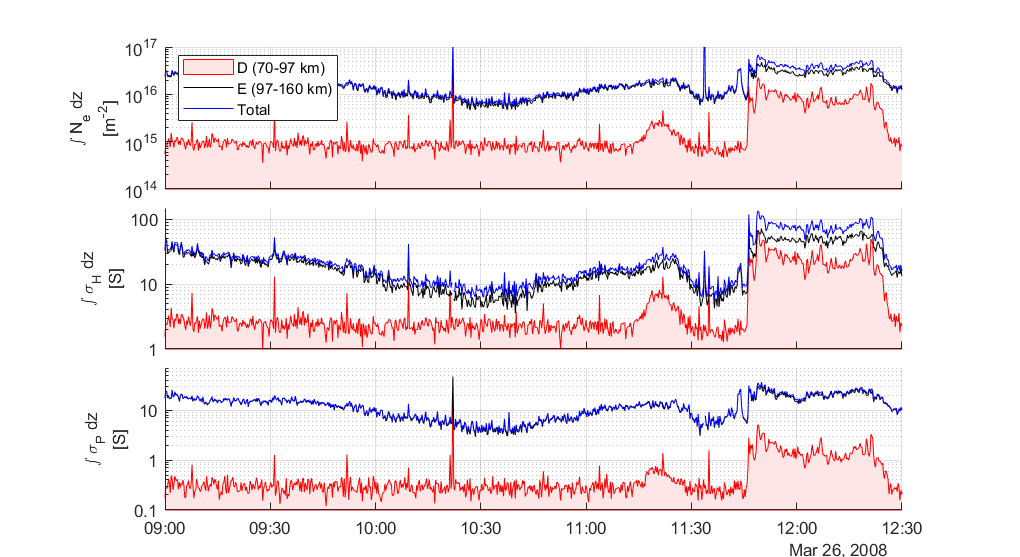

h1 = figure;
timeMinStr = '26-Mar-2008 09:00';
timeMaxStr = '26-Mar-2008 12:30';
yaxisLim = [10^14 10^17];
xaxisLim = [datetime(timeMinStr), datetime(timeMaxStr)];
p = create_panels(h1,'totalPanelNo',3,'panelHeight',30);
t = datetime(datevec(time));
p(1,1).select();
area(t,DNe,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
plot(t,ENe,'k');
hold on;
plot(t,TNe,'b');
grid on;
set(gca,'YScale','log',...
    'YLim',yaxisLim,'YTick',[10^14,10^15,10^16,10^17],...
    'XTickLabel','','XLim',xaxisLim);
ylabel({'\int N_e dz','[m^-^2]'})
legend('D (70-97 km)','E (97-160 km)','Total','Location','northwest');

TH(TH>150) = nan;
DH(DH>150) = nan;
EH(EH>150) = nan;

p(1,2).select();
yaxisLim = [1 150];
area(t,DH,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
plot(t,EH,'k');
hold on;
plot(t,TH,'b');
grid on;
set(gca,'YScale','log',...
    'YLim',yaxisLim,'YTick',[1,10,100,1000],'YTickLabel',{'1','10','100','1000'},...
    'XTickLabel','','XLim',xaxisLim);
ylabel({'\int \sigma_H dz','[S]'})

p(1,3).select();
yaxisLim = [0.1 70];
DP(DP>70) = nan;
area(t,DP,'FaceColor',[1 0.9 0.9],'EdgeColor','r');
hold on;
EP(EP>70) = nan;
plot(t,EP,'k');
hold on;
TP(TP>70) = nan;
plot(t,TP,'b');
grid on;
set(gca,'YScale','log',...
    'YLim',yaxisLim,'YTick',[0.1,1,10,100],'YTickLabel',{'0.1','1','10','100'},...
    'XLim',xaxisLim);
ylabel({'\int \sigma_P dz','[S]'})

## Compare Yiqun's THEMIS Conductivities to PFISR

iBeam = 13;
% DregionAltIndx = find_altitude(alt(iBeam,:)',70):1:find_altitude(alt(iBeam,:)',107); 
% EregionAltIndx = find_altitude(alt(iBeam,:)',107)+1:1:find_altitude(alt(iBeam,:)',160);

h = figure;
timeMinStr = '26-Mar-2008 09:00';
timeMaxStr = '26-Mar-2008 12:30';
p = create_panels(h,'totalPanelNo',2,'panelHeight',30);

% PFISR
t = datetime(datevec(time));
colormap(inferno);
yaxisLim = [70 160];
p(1,1).select();
inputNe = squeeze(Ne(:,iBeam,:));
inputNe = interp_nans(inputNe);
plot_2D_time_series(time,alt(iBeam,:),log10(inputNe'),0.25,0,timeMinStr,timeMaxStr); 
colorbar;
caxis([9,12]);
ylim(yaxisLim);
ylabel({'N_e [m^-^3]','Alt [km]'});

% t = datetime(datevec(yiqun.Ar.thd.time));
p(1,2).select();
inputNe = yiqun.Ar.thd.NeOut * 10^6;
inputNe = interp_nans(inputNe);
plot_2D_time_series(yiqun.Ar.thd.time,yiqun.Ar.thd.alt,log10(inputNe'),0.25,0,timeMinStr,timeMaxStr); 
colorbar;
caxis([9,12]);
ylim(yaxisLim);
ylabel({'ThmD N_e [m^-^3]','Alt [km]'});
label_time_axis(yiqun.Ar.thd.time,1,0.5,timeMinStr,timeMaxStr);

function I = integrate_altitude(alt,y)
    I = trapz(alt*1000,y,2);
end